# Getting the PSD from data through Blackman-Tukey estimator

## Introduction

In this tutorial you will learn how to estimate the PSD of a random process from a time series through the Blackman-Tukey estimator. The time series is assumed to be a realisation of a zero-mean random process. The PSD estimation is obtained by (1) estimating the autocovariance function of the data; (2) applying a window to improve the estimator performance; (3) obtaining the discrete-time Fourier transform (DTFT) of the autocovariance function modified by the window.

The dataset employed in this tutorial is '*database/case_01_Mann_1V*', which includes a synthetic time series of the longitudinal component of turbulent wind fluctuation (zero mean), according to the Mann's model, and the related true spectrum. This allows comparison between the estimated PSD and the true PSD. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

N_f             = 100;      % number of elements of the frequency vector

M               = 50;       % máximum lag considered for the estimation
                            % of the autocovariance function

method  = 'biased_matlab';  % Method for estimating the autocovariance function.
                            % For a list of estimation methods, see function 
                            % 'initialise_gamma'.                            
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

window_name = 'Hamming';    % Name of the window applied to the estimated 
                            % autocovariance function.
                            % For a list of window names, see function
                            % 'initialise_window'. 
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

%%% Plot parameters
font_size       = 14;
figure_position = [0 0 1000 400];
CC              = colororder;
color_estimated = CC(5,:);
color_true      = CC(4,:);

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a `S` object. For details related to the fields of these objects, see functions `initialise_data` and `initialise_S`.

load case_01_Mann_1V.mat

Have a look at the time series considered. 

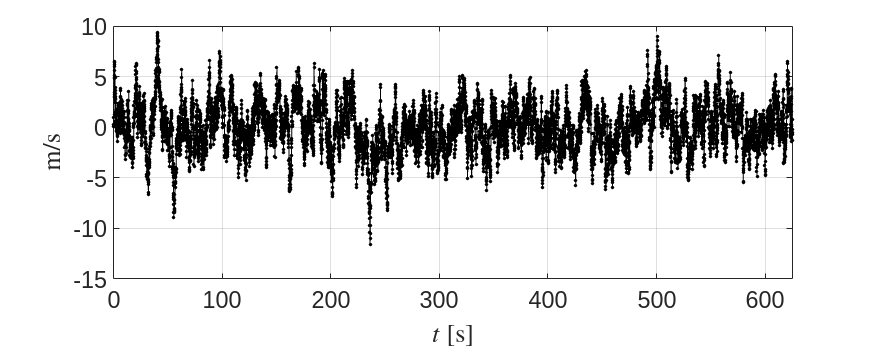

figure

x = data_Mann.x_values;
y = data_Mann.y_values;
plot(x,y,'.-k')

grid on
xlabel('$t$ [s]','Interpreter','latex')
ylabel('m/s','Interpreter','latex')
xlim([0 data_Mann.x_values(end)])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum, `f_vector`, will be defined within this frequency range. Log scale will be employed for convenience (see tutorial '*getting_S_from_data_through_sample_spectrum*' for details).

delta_t     = data_Mann.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_Mann.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = logspace(log10(f_min),log10(f_max),N_f);

Initialise an S object  with the fields required by function `get_S_data_BT`. 

S0 = initialise_S('x_values', f_vector);

Initialise a `gamma` object  with the fields required by function `get_S_data_BT`. 

gamma_fun0 = initialise_gamma('M', M, 'method', method);

Initialise a `window` object with the fields required by function `get_S_data_BT`.

window = initialise_window('name',window_name);

Compute the PSD of the data. Since the data is univariate, there is no need to specify the column with parameter `k_index` (see details in function get_S_data`_BT`).

[ S_BT ] = get_S_data_BT(data_Mann, S0, gamma_fun0, window);

Plot the obtained PSD together with the true spectrum.

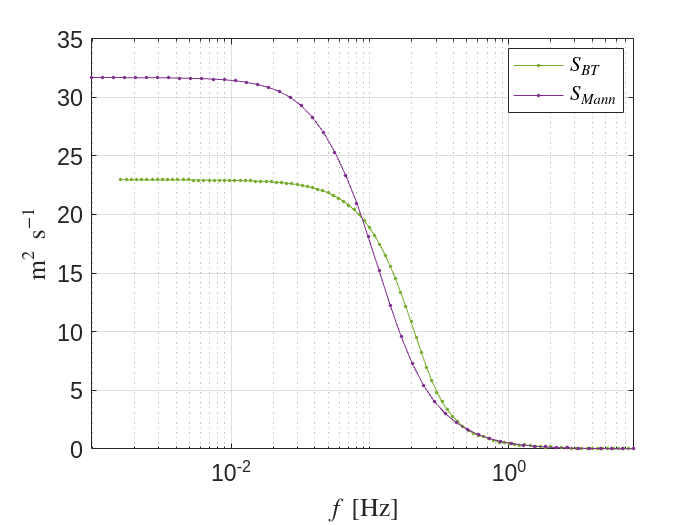

figure

x = S_BT.x_values;
y = S_BT.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

legend({'$S_{BT}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')

set(gca,'fontsize',font_size)
set(gca,'Xscale','log')

The performance of the BT estimator depends greatly on the choice for parameter `M`, the maximum lag considered in the autocovariance function estimated from the data. A good choice for `M` is a lag value for which the autocovariance function has reasonably faded out to zero. Have a look at the estimated autocovariance function, and reconsider the value of parameter `M` defined above.

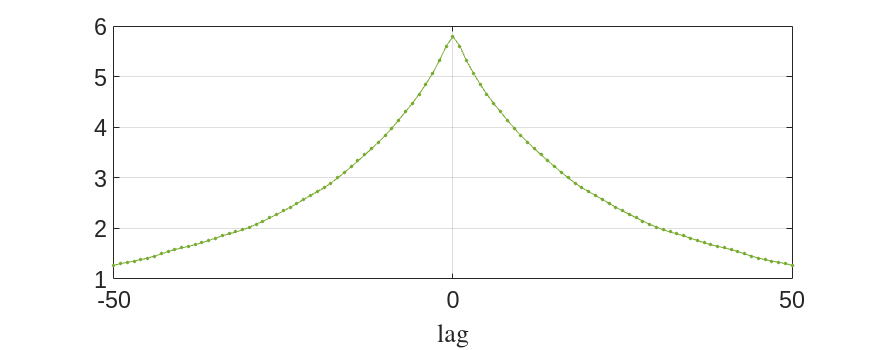

[gamma_fun] = get_gamma_data(data_Mann, gamma_fun0);

figure

x = gamma_fun.xlag_values;
y = gamma_fun.y_values;
plot(x,y,'.-','Color',color_estimated)

grid on
xlabel('lag','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

For this data set, a good `M` value would be around `M=150`. See the estimated PSD for this value.

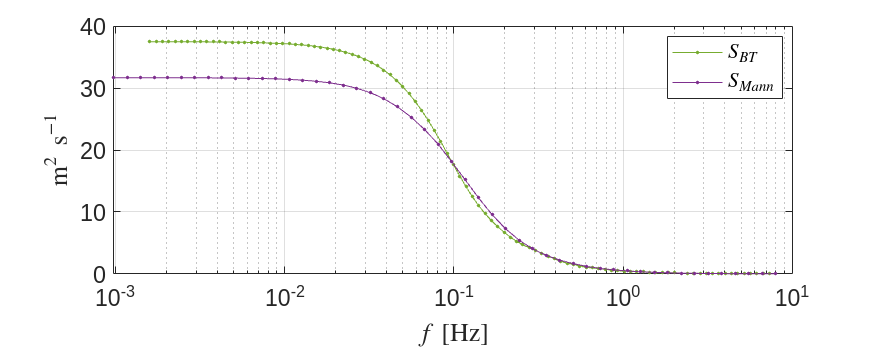

M_good_enough = 150;

gamma_fun0 = initialise_gamma('M', M_good_enough, 'method', method);

[ S_BT ] = get_S_data_BT(data_Mann, S0, gamma_fun0, window);

x = S_BT.x_values;
y = S_BT.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

legend({'$S_{BT}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')

set(gca,'fontsize',font_size)
set(gca,'Xscale','log')

For the case of wind turbulence, two common representations are the product $f \cdot S$ in log-linear scales, and $S$ in log-log scales.

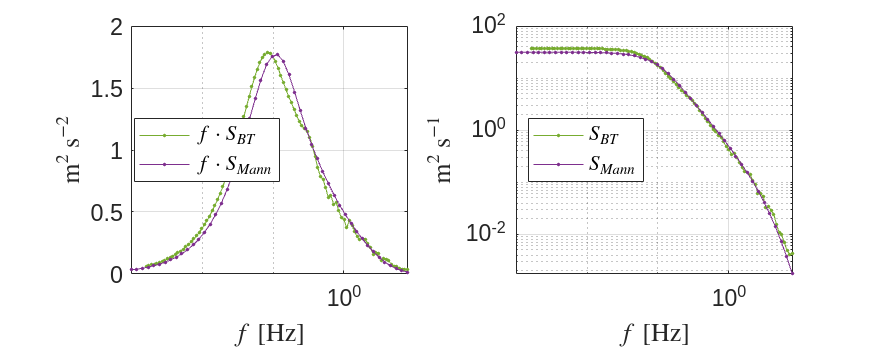

figure


subplot(1,2,1)

x = S_BT.x_values;
y = S_BT.y_values;
plot(x,x.*y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-','color',color_true)

grid on
legend({'$f \cdot S_{BT}$','$f \cdot S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$  s$^{-2}$','Interpreter','latex')
set(gca,'Xscale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

x = S_BT.x_values;
y = S_BT.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

grid on
legend({'$S_{BT}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ s$^{-1}$','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'Yscale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the PSD is a continuous function of the frequency, and it can be evaluated at any frequency value. 

- However, the PSD estimated from a discrete time series is periodic for frequencies higher thant $f_{max} $. You can check it just by changing `f_vector` accordingly (and ploting the PSD in x-linear scale). 

- Also, the estimated spectrum for frequencies below $f_{min}$ is likely to be inaccurate because the time simulation of the data, `t_sim`, is not long enough to capture such small frequencies.

- The Blackman-Tukey estimator performs reasonably well as compared with the sample spectrum. One of the reasons is the effect of applying a window to the estimated covariance function. You can check the impact of using different windows on the estimated PSD by changing the parameter `window_name`.

- As it was discussed, low `M` values lead to a bad PSD estimation, because the information contained in the autocovariance function is not fully captured. However, be aware that increasing the maximum lag `M` arbitrarily may also have a bad impact on the PSD estimation. This is so because estimating the covariance function from data tends to be innacurate for large lags. See tutorial '*getting_gamma_from_data.mlx*' for details.

- In addition, for specific combinations of the input parameters, the estimated PSD through Blackman-Tukey approach may lead to negative values of the PSD, which is not realistic because the PSD is, by definition, always positive (this does not apply to the cross spectrum, CPSD, bewteen two variables). This leads to discontinuities in the y-log plot. This can be addressed just by taking the absolute value of the obtained PSD.